**DARPA SUBOFF Sail**

Sail forebody length                                            =0.325521 Ft

Sail Parallel Middle Body Length                         =0.200521 Ft

Sail Afterbody length                                           =0.682292 Ft

Sail Total Length                                                 =1.208333 Ft

Span of Sail with uniform Profile                         =0.674479 Ft

Zmax= one half of the maximum sail thickness  =0.109375 Ft

**Main Dimension**

% Define sail dimensions
L_Sail_forebody_ft = 0.325521; % Sail forebody length in feet
L_parallel_middle_ft = 0.200521; % Sail parallel middle body length in feet
L_afterbody_ft = 0.682292; % Sail afterbody length in feet
L_total_ft = 1.208333; % Sail total length in feet
Span_sail_ft = 0.674479; % Span of sail with uniform profile in feet
Zmax = 0.109375; % One half of the maximum sail thickness in feet

**Sail Forebody**

% Calculate sail surface points
% 3.032986 Ft <= X <= 3.358507 Ft
% y<= 1.507813 Ft
DivisionsSailFore = 60;
StepSailFore = L_Sail_forebody_ft / DivisionsSailFore;
XSailFore= 3.032986:StepSailFore:3.358507;
% Calculate Z1Fore
D = 3.072 * (XSailFore - 3.032986);
A = 2 * D .* (D - 1).^4;
B = (1/3) * (D.^2) .* (D - 1).^3;
C = 1 - ((D - 1).^4) .* (4 * D + 1);
Z1Fore = Zmax * (2.094759 * A + 0.2071781 * B + C).^0.5;
% Take absolute value of Z1Fore
Z1Fore = abs(Z1Fore);

**Sail Parallel Middlebody**

% ... (Sail Parallel Middlebody)
%3.358507 Ft <= X <= 3.559028
%y<=1.507813
DivisionsSailParallel = 60;
StepSailParallel=(3.559028-3.358507)/DivisionsSailParallel;
% ... (Sail Parallel Middlebody calculations)
% y <= 1.507813 Ft
XSailParallel= 3.358507:StepSailParallel:3.559028;
ZSailParallel=ones(1, DivisionsSailParallel + 1) * Zmax;

**Sail Afterbody**

% (Sail Afterbody calculations)
%(Revised 11 January 1989)
%For 3.559028 Ft <= x <= 4.241319 Ft
%y <= 1.507813 Ft
DivisionsSailAft = 60;
StepSailAft=(4.241319-3.559028)/DivisionsSailAft;
XSailAft=3.559028:StepSailAft:4.241319;
E  = (4.241319 - XSailAft) / 0.6822917;
Z1SailAft=Zmax .* ((2.238361 .* E .* ((E-1).^4))+(3.106529 .* (E .^2) .* ((E-1) .^3))+(1-((E-1) .^4) .* (4.*E +1)));

**SAIL Side**

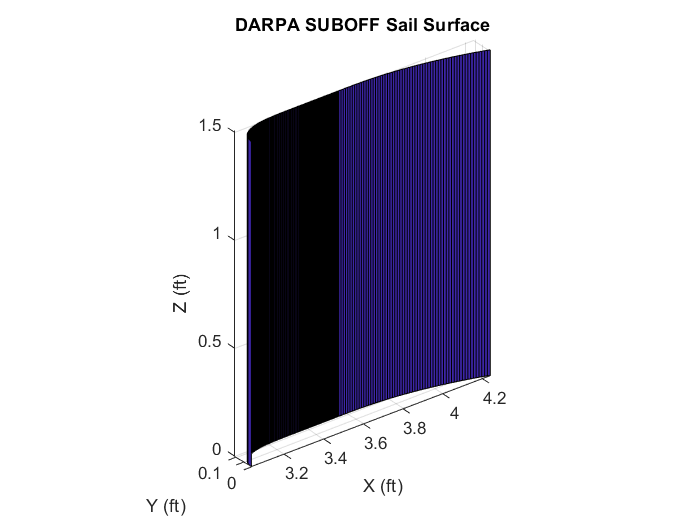

XSailSide= [XSailFore XSailParallel XSailAft];
Z1=[Z1Fore ZSailParallel Z1SailAft];
ZLow=0;
ZHigh=1.507813;
% Calculate Ymax, Ymin, and Ystep
X=repmat(XSailSide,2,1);
Y = repmat(Z1,2,1);
Z = [ ZLow.* ones(1,size(X,2));ZHigh.* ones(1,size(X,2))];

surf(X,Y,Z)

axis equal
xlabel('X (ft)');
ylabel('Y (ft)');
zlabel('Z (ft)');
title('DARPA SUBOFF Sail Surface');

**CSV Export**

%export to CSV
exportXYZtoCSV('XYZ_data_SailSide.csv', X, Y, Z);

'exportXYZtoCSV' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\AlucarD\Documents\GitHub\DARPA-SUBOFF-DTRC-Automated-Surface\MATLAB
    D:\!Marine\!master\Matlab\Clean Code

Change the MATLAB current folder or add its folder to the MATLAB path.